clear; close all;
load('Maze.mat');

Main loop

tic
[AStarPath, AStarStats] = A_Star(Maze);
AStarTime = toc;

tic
[DijkstraPath, DijkstraStats] = DijkstrA(Maze);
DijkstraTime = toc;


Stats and Plots

% A* path and stats
disp('--------------------------------------------');

--------------------------------------------


disp('A* Algorithm')

A* Algorithm


fprintf('  Pushes    : %d\n',   AStarStats.pushes);

  Pushes    : 687


fprintf('  Pops      : %d\n',   AStarStats.pops);

  Pops      : 626


fprintf('  Path cost : %.4f\n', AStarStats.cost);

  Path cost : 64.7279


fprintf('  Time (s)  : %.6f\n', AStarTime);

  Time (s)  : 0.023285


disp('--------------------------------------------');

--------------------------------------------


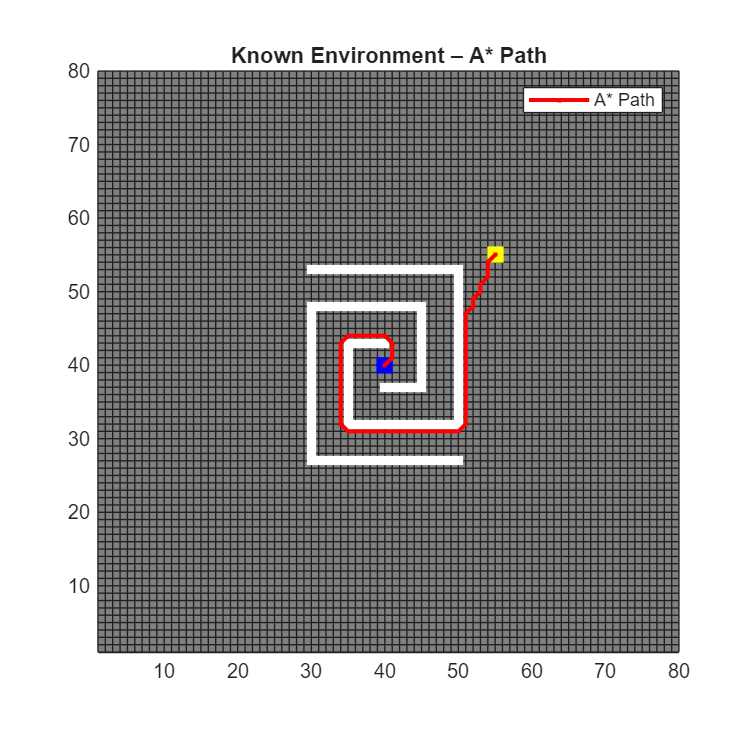

figure(1); CreateMaze_1; hold on;      
p1 = plot(AStarPath(:,1), AStarPath(:,2), '.-r', 'LineWidth', 2, 'DisplayName', 'A* Path'); 
legend(p1, {'A* Path'}, 'Location', 'northeast');
title('Known Environment – A* Path');

 
% Dijkstra path and stats
disp('--------------------------------------------');

--------------------------------------------


disp('Dijkstra Algorithm')

Dijkstra Algorithm


fprintf('  Pushes    : %d\n',   DijkstraStats.pushes);

  Pushes    : 3392


fprintf('  Pops      : %d\n',   DijkstraStats.pops);

  Pops      : 3097


fprintf('  Path cost : %.4f\n', DijkstraStats.cost);

  Path cost : 64.7279


fprintf('  Time (s)  : %.6f\n', DijkstraTime);

  Time (s)  : 0.075859


disp('--------------------------------------------');

--------------------------------------------


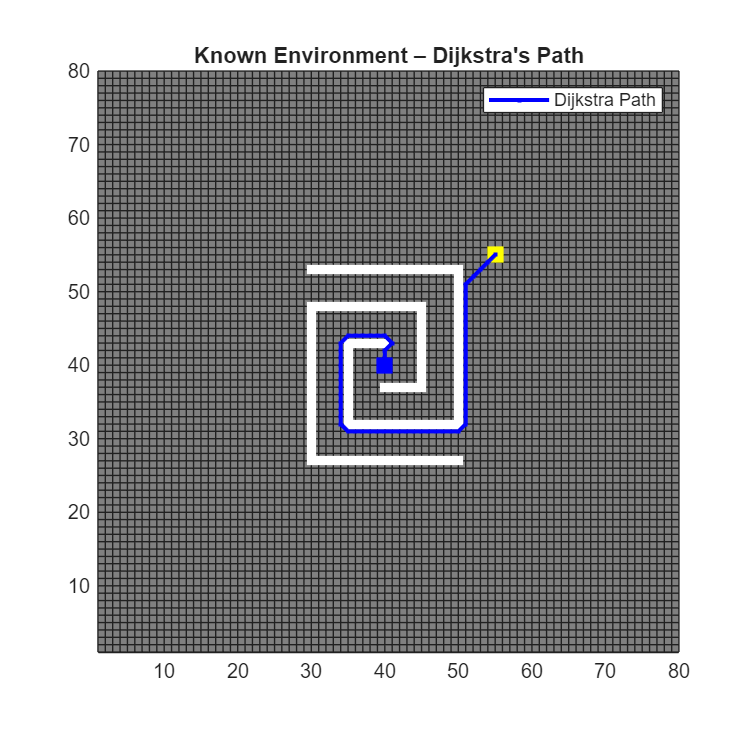

figure(2); CreateMaze_1; hold on;      
p2 = plot(DijkstraPath(:,1), DijkstraPath(:,2), '.-b', 'LineWidth', 2, 'DisplayName', 'Dijkstra Path'); 
legend(p2, {'Dijkstra Path'}, 'Location', 'northeast');
title("Known Environment – Dijkstra's Path");